ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');

upPeaks = [];
upFrequencies = [];
upMeanWave = [];
upPeakFlashResponse = [];
upChargeFlashResponse = [];

downPeaks = [];
downFrequencies = [];
downMeanWave = [];
downPeakFlashResponse = [];
downChargeFlashResponse = [];
%choose which protocols to look at
priorityOrder_1 = {'MiniPSCs'}; %first field name should be one of these. Priority is in given order
priorityOrder_1b = {'Flash'};
priorityOrder_2 = {'_ff'; ''}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Excitation'};
cantHave_1 = [];
cantHave_2 = {'Extracellular', 'CurrentClamp'}; %avoid anything with these tags
rigMandates = []; %use only cells with LED spot diameter = 500

%ups first
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc2, pass2] = getLoc(struct_i, priorityOrder_1b, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    if pass || pass2
        continue
    end
    
    upPeaks(end+1) = loc.Analysis_Results.meanWaveAmplitude;
    upFrequencies(end+1) = loc.Analysis_Results.numWaves/loc.Analysis_Results.numberOfUsableResponses;
    upMeanWave(end+1, :) = loc.Analysis_Results.meanWave;
    upPeakFlashResponse(end + 1) =  mean(loc2.Analysis_Results.ON_maxNegativePeakByEpoch);
    upChargeFlashResponse(end + 1) = mean(loc2.Analysis_Results.totalChargeByEpoch);
end
%downs second
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    if pass
        continue
    end

    downPeaks(end+1) = loc.Analysis_Results.meanWaveAmplitude;
    downFrequencies(end+1) = loc.Analysis_Results.numWaves/loc.Analysis_Results.numberOfUsableResponses;
    downMeanWave(end+1, :) = loc.Analysis_Results.meanWave;
    downPeakFlashResponse(end + 1) =  mean(loc2.Analysis_Results.ON_maxNegativePeakByEpoch);
    downChargeFlashResponse(end + 1) = mean(loc2.Analysis_Results.totalChargeByEpoch);
end


## Amplitude of responses

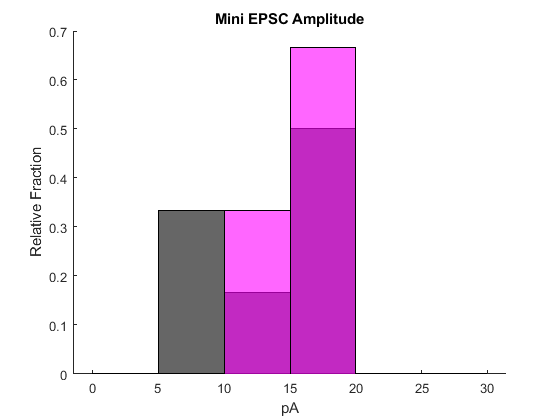

edgs = [0:5:30];
figure
title('Mini EPSC Amplitude')
hold on
h1 = histogram(upPeaks, 'FaceColor', 'k', 'BinEdges', edgs, 'Normalization', 'probability');
h2 = histogram(downPeaks, 'FaceColor', 'm', 'BinEdges', edgs, 'FaceAlpha', 0.6, 'Normalization', 'probability');
%h2.BinWidth = h1.BinWidth;
xlabel('pA')
ylabel('Relative Fraction')

## Frequency of responses

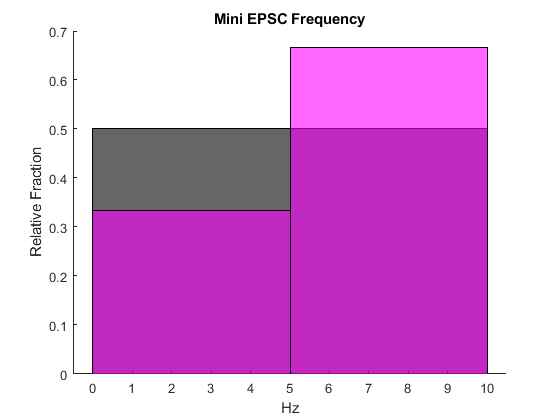

figure
title('Mini EPSC Frequency')
hold on
h1 = histogram(upFrequencies, 'FaceColor', 'k', 'Normalization', 'probability');
h2 = histogram(downFrequencies, 'FaceColor', 'm', 'FaceAlpha', 0.6, 'Normalization', 'probability');
h2.BinWidth = h1.BinWidth;
xlabel('Hz')
ylabel('Relative Fraction')

## Mean waveforms

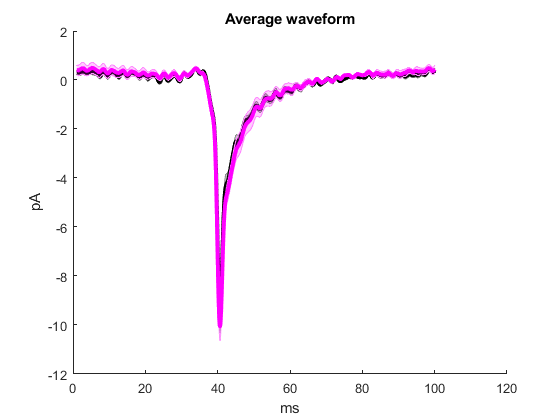

upMean = mean(upMeanWave);
upErr = std(upMeanWave)/sqrt(size(upMeanWave, 1));
downMean = mean(downMeanWave);
downErr = std(downMeanWave)/sqrt(size(downMeanWave, 1));

xvals = linspace(1, size(upMeanWave, 2)/10, size(upMeanWave, 2));
figure
title('Average waveform')
shadedErrorBar(xvals, upMean, upErr, 'lineprops', {'color', [0, 0, 0]/255, 'linewidth', 3})
shadedErrorBar(xvals, downMean, downErr, 'lineprops', {'color', [255, 0, 255]/255, 'linewidth', 3})
ylabel('pA')
xlabel('ms')

        a = analysisSuperClass;
        [freqs, power] = a.buildPowerSpectrum(downMean(1:350), 0.035, .0001);

## Flash Response vs Minis

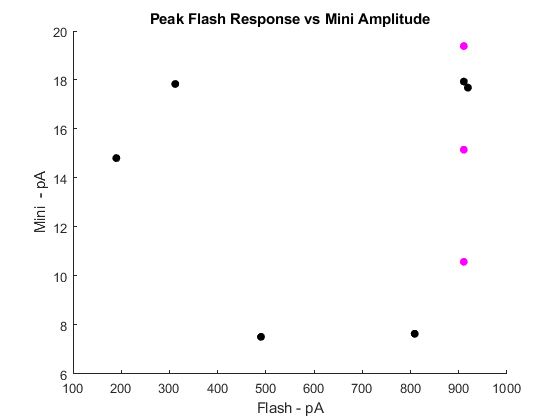

figure
title('Peak Flash Response vs Mini Amplitude')
hold on
scatter(-upPeakFlashResponse, upPeaks, 'k', 'filled')
scatter(-downPeakFlashResponse, downPeaks, 'm', 'filled')
xlabel('Flash - pA')
ylabel('Mini  - pA')

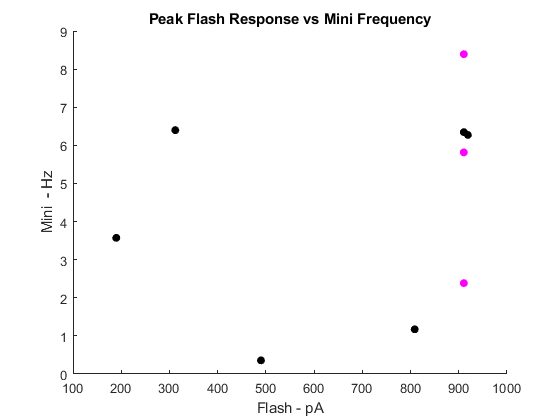


figure
title('Peak Flash Response vs Mini Frequency')
hold on
scatter(-upPeakFlashResponse, upFrequencies, 'k', 'filled')
scatter(-downPeakFlashResponse, downFrequencies, 'm', 'filled')
xlabel('Flash - pA')
ylabel('Mini  - Hz')

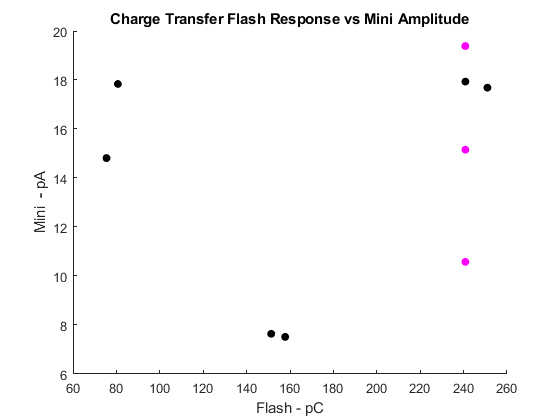


figure
title('Charge Transfer Flash Response vs Mini Amplitude')
hold on
scatter(-upChargeFlashResponse, upPeaks, 'k', 'filled')
scatter(-downChargeFlashResponse, downPeaks, 'm', 'filled')
xlabel('Flash - pC')
ylabel('Mini  - pA')

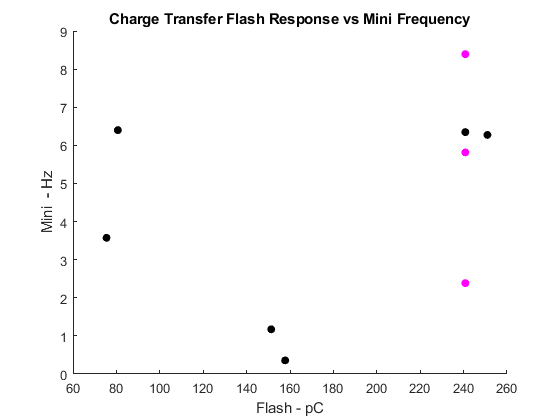


figure
title('Charge Transfer Flash Response vs Mini Frequency')
hold on
scatter(-upChargeFlashResponse, upFrequencies, 'k', 'filled')
scatter(-downChargeFlashResponse, downFrequencies, 'm', 'filled')
xlabel('Flash - pC')
ylabel('Mini  - Hz')